# Chapter 14 ATAP Exercises

## Discussion of High-Order Interpolation

#### Mason Mault July 2025

Exercises Worked:

Exercise 14.1: Convergence as $n\to \infty \;$

Exercise 14.2: Too many wiggles

Exercise 14.3: Your own textbook

Exercise 14.4: Spline Interpolants

**Exercise 14.1: Convergence as **$n\to \infty \;$

Based on the theorems of this book, for interpolation in Chebyshev points, for which functions do we know that increasing $n$ must lead to an improvement?

The theorems ensuring a decrease in error with increasing $n$ pertain to differentiable and analytic functions. Namely, Theorems 7.1, 7.2, 8.1, and 8.2 describe errors and coefficient magnitudes that decrease with increasing $n$.

**Exercise 14.2: Too many wiggles**

Find the error in the following 2002 textbook quote by plotting the roots in the complex plane of the derivative of $f\left(x\right)=\exp \left(x\right)\;\tanh \left(2x-1\right)$.

 "Because its derivative has $n-1$ zeros, a polynomial of degree $n$ has $n-1$ extreme or inflection points. Thus, simply put, a high-degree polynomial necessarily has many wiggles, which may bear no relation to the data to be fit" 

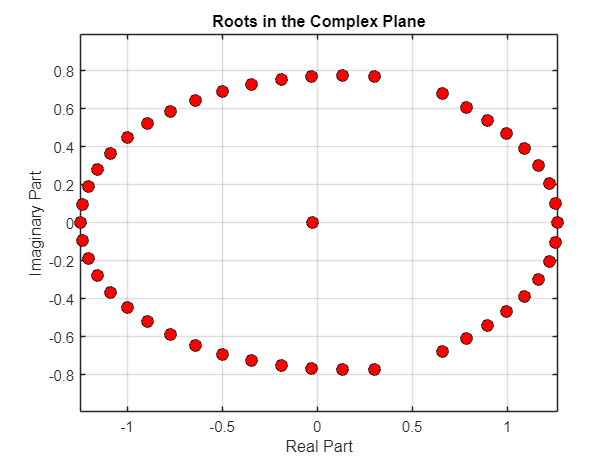

f = chebfun(@(x) exp(x)*tanh(2*x - 1));
derf = diff(f);

rootList = roots(derf, 'all');

figure
plot(real(rootList), imag(rootList), 'ko', 'MarkerFaceColor', 'r', 'MarkerSize', 8)
axis equal
grid on
xlabel('Real Part')
ylabel('Imaginary Part')
title('Roots in the Complex Plane')

length(rootList)

ans = 47

a = imag(rootList) == 0;
numRealRoots = sum(a)

numRealRoots = 3

Although the derivative has 47 total roots, only 3 lie on the real line, and the resulting interpolant, nor its derivative, have "many wiggles", as shown below.

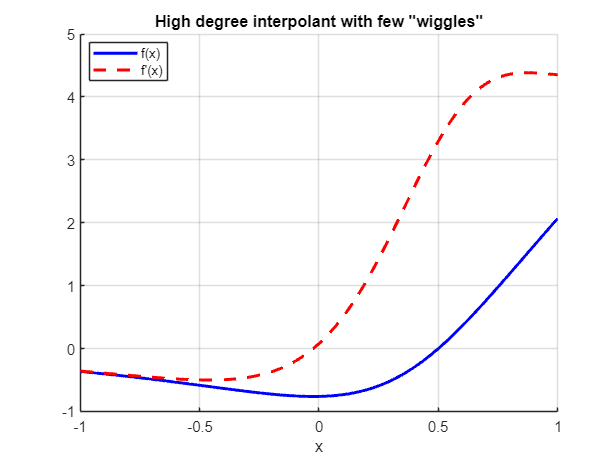

figure
hold on
plot(f, 'b', 'LineWidth', 2)         
plot(derf, 'r--', 'LineWidth', 2)     
legend({'f(x)', 'f''(x)'}, 'Location', 'Best')
xlabel('x')
ylabel('')
title('High degree interpolant with few "wiggles"')
grid on

**Exercise 14.3: Your own textbook**

Examine your own textbooks treatment of polynomial interpolation. Using a pdf of Burden and Faires *Numerical Analysis* 9th Edition.

**a)** What does it say about behavior for large $n$? If it asserts that this behavior is problematic, is this conclusion based on the assumption of equally spaced points, and does the text make this clear?

The section on polynomial interpolation shows polynomial interpolant evaluation away from the node, calling it "increasingly inaccurate" and "rather a dramatic failure". In this section, I have not found that the text emphasizes this error is caused by equally spaced nodes.

**b)** Does it mention interpolation in Chebyshev points? Does it state that such interpolants converge exponentially for analytic functions?

It is not mentioned in the Lagrange polynomial section (though I think it should be), but there is a section devoted to Chebyshev polynomials. It states they provide "an optimal placing of interpolating points to minimize the error in Lagrange interpolation" and "a means of reducing the degree of an approximating polynomial with minimal loss of accuracy". I did not find that it explicitly states anything about analytic functions converging exponentially. 

**c)** Does it mention the barycentric formula?

My control-f search for "barycentric" returned no hits in the textbook.

**d)** Does it claim that one should use a Newton rather than a Lagrange interpolation formula for numerical work? (This is a myth)

In the section on Lagrange interpolation, it claim that Newtons method is often used instead of Lagrange interpolation for numerical work. 

**Exercise 14.4: Spline Interpolants**

Compare the interpolation of $g\left(x\right)=\frac{1}{\left(1+25x^2 \right)}$ , the Runge funciton, by a cubic spline in equally spaced points and a Chebyshev interpolant in Chebyshev point as $n\to \infty \ldotp$ Then repeat for $h\left(x\right)=|x+\frac{1}{\pi \;}|$ on [-1, 1], then for $h\left(x\right)$ on [0, 1].

gTrue = chebfun(@(x) 1/(1 + 25*x.^2));

list = 2:50:300;
errCheb = zeros(length(list), 1);
errSpline = errCheb;

for j = 1:length(list)
    n = list(j);
    % equispaced points and spline
    s = linspace(-1, 1, n + 1);
    gSpline = chebfun((@(x) spline(s, 1./(1 + 25*s.^2), x)));
    % Chebyshev interpolant
    gCheb = chebfun(gTrue, n + 1);
    % append errors
    errCheb(j) = norm(gCheb - gTrue, inf);
    errSpline(j) = norm(gSpline - gTrue, inf);  
end

Plot the error for each scheme as a function of $n$, as well as the interpolants for two (arbitrary) selected values of $n$. These values of $n$ are reused for $h\left(x\right)$

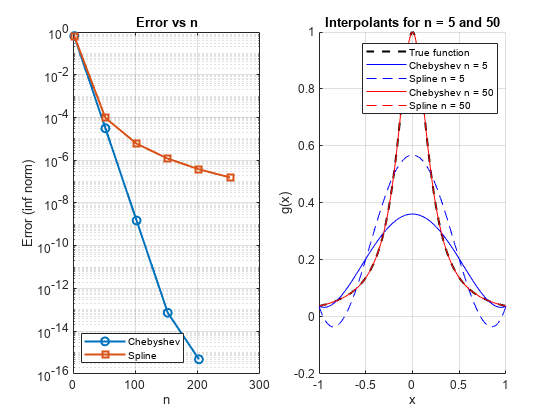

% interpolants to plot
n1 = 5;
n2 = 50;

% Chebyshev interpolants
gCheb1 = chebfun(gTrue, n1 + 1);
gCheb2 = chebfun(gTrue, n2 + 1);

% spline interpolants
s1 = linspace(-1, 1, n1 + 1);
s2 = linspace(-1, 1, n2 + 1);
gSpline1 = chebfun(@(x) spline(s1, 1./(1 + 25*s1.^2), x), [-1, 1]);
gSpline2 = chebfun(@(x) spline(s2, 1./(1 + 25*s2.^2), x), [-1, 1]);

figure;

% error
subplot(1, 2, 1);
semilogy(list, errCheb, '-o', list, errSpline, '-s', 'LineWidth', 1.5);
grid on;
legend('Chebyshev', 'Spline', 'Location', 'southwest');
xlabel('n'); ylabel('Error (inf norm)');
title('Error vs n');

% interpolants
subplot(1, 2, 2); hold on;
plot(gTrue, 'k--', 'LineWidth', 1.5, 'DisplayName', 'True function');

plot(gCheb1, 'b-', 'DisplayName', 'Chebyshev n = 5');
plot(gSpline1, 'b--', 'DisplayName', 'Spline n = 5');

plot(gCheb2, 'r-', 'DisplayName', 'Chebyshev n = 50');
plot(gSpline2, 'r--', 'DisplayName', 'Spline n = 50');

xlabel('x'); ylabel('g(x)');
title('Interpolants for n = 5 and 50');
legend('show'); grid on;

For all values of $n$ the Chebyshev interpolant gives a better approximation to the Runge function in terms of the $L_{\infty }$ norm, with machine precision reached at $n\approx 200$. The Runge function is analytic, and by the ideas of Chapter 8, the Chebyshev interpolant must converge analytically. 

Moving to the function $h\left(x\right)=|x+\frac{1}{\pi \;}|$ , first on the domain [-1, 1]

hTrue = chebfun(@(x) abs(x + 1/pi), 'splitting', 'on');
listh = 2:50:300;
errChebh = zeros(length(listh), 1);
errSplineh = errChebh;

for j = 1:length(listh)
    n = listh(j);
    % equispaced points and spline on [-1, 1]
    s = linspace(-1, 1, n + 1);
    hSpline = chebfun((@(x) spline(s, abs(s + 1/pi), x)));
    % Chebyshev interpolant on [-1, 1]
    hCheb = chebfun(hTrue, n + 1, 'splitting', 'on');
    % append errors
    errChebh(j) = norm(hCheb - hTrue, inf);
    errSplineh(j) = norm(hSpline - hTrue, inf);  
end

Again, plot the error for each scheme as a function of $n$, as well as the interpolants for two values of $n$.

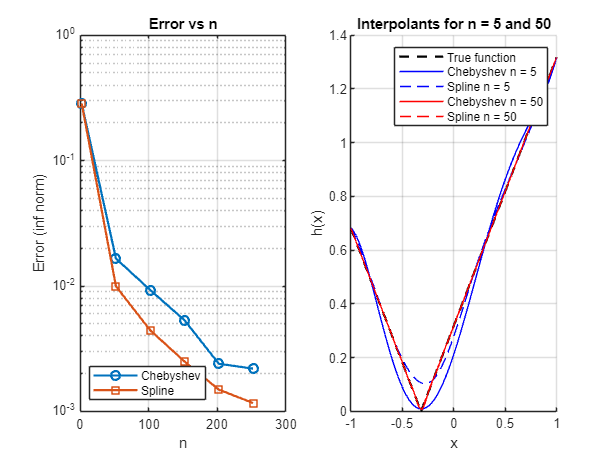

% Chebyshev interpolants
hCheb1 = chebfun(hTrue, n1 + 1, 'splitting', 'off');
hCheb2 = chebfun(hTrue, n2 + 1, 'splitting', 'off');

% spline interpolants
s1 = linspace(-1, 1, n1 + 1);
s2 = linspace(-1, 1, n2 + 1);
hSpline1 = chebfun(@(x) spline(s1, abs(s1 + 1/pi), x), [-1, 1]);
hSpline2 = chebfun(@(x) spline(s2, abs(s2 + 1/pi), x), [-1, 1]);

figure;

% error
subplot(1, 2, 1);
semilogy(listh, errChebh, '-o', listh, errSplineh, '-s', 'LineWidth', 1.5);
grid on;
legend('Chebyshev', 'Spline', 'Location', 'southwest');
xlabel('n'); ylabel('Error (inf norm)');
title('Error vs n');

% interpolants
subplot(1, 2, 2); hold on;
plot(hTrue, 'k--', 'LineWidth', 1.5, 'DisplayName', 'True function');

plot(hCheb1, 'b-', 'DisplayName', 'Chebyshev n = 5');
plot(hSpline1, 'b--', 'DisplayName', 'Spline n = 5');

plot(hCheb2, 'r-', 'DisplayName', 'Chebyshev n = 50');
plot(hSpline2, 'r--', 'DisplayName', 'Spline n = 50');

xlabel('x'); ylabel('h(x)');
title('Interpolants for n = 5 and 50');
legend('show'); grid on;

Contrary to the first example, in terms of the $L_{\infty }$ norm the spline wins for all values of $n$ tested. The function has a discontinuity at $x=-\frac{1}{\pi \;}$, one perspective why splines perform better.

Again, $h\left(x\right)=|x+\frac{1}{\pi \;}|$, now on the domain [0, 1].

hTrue2 = chebfun(@(x) abs(x + 1/pi), [0, 1], 'splitting', 'on');

listh2 = 2:50:300;
errChebh2 = zeros(length(listh2), 1);
errSplineh2 = errChebh2;

for j = 1:length(listh2)
    n = listh2(j);
    % equispaced points and spline on [0, 1]
    s = linspace(0, 1, n + 1);
    hSpline = chebfun(@(x) spline(s, abs(s + 1/pi), x), [0, 1]);
    % Chebyshev interpolant on [0, 1]
    hCheb = chebfun(hTrue2, 'splitting', 'off', n + 1);
    % append errors
    errChebh2(j) = norm(hCheb - hTrue2, inf);
    errSplineh2(j) = norm(hSpline - hTrue2, inf);  
end

For the final time, plot the error for each scheme as a function of $n$, as well as the interpolants for two values of $n$.

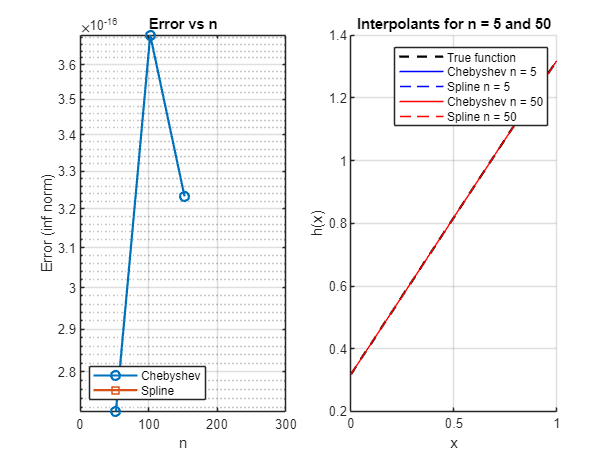

% Chebyshev interpolants
hCheb12 = chebfun(hTrue2, n1 + 1, 'splitting', 'off');
hCheb22 = chebfun(hTrue2, n2 + 1, 'splitting', 'off');

% spline interpolants
s12 = linspace(0, 1, n1 + 1);
s22 = linspace(0, 1, n2 + 1);
hSpline12 = chebfun(@(x) spline(s12, abs(s12 + 1/pi), x), [0, 1]);
hSpline22 = chebfun(@(x) spline(s22, abs(s22 + 1/pi), x), [0, 1]);

figure;

% error
subplot(1, 2, 1);
semilogy(listh2, errChebh2, '-o', listh2, errSplineh2, '-s', 'LineWidth', 1.5);
grid on;
legend('Chebyshev', 'Spline', 'Location', 'southwest');
xlabel('n'); ylabel('Error (inf norm)');
title('Error vs n');

% interpolants
subplot(1, 2, 2); hold on;
plot(hTrue2, 'k--', 'LineWidth', 1.5, 'DisplayName', 'True function');

plot(hCheb12, 'b-', 'DisplayName', 'Chebyshev n = 5');
plot(hSpline12, 'b--', 'DisplayName', 'Spline n = 5');

plot(hCheb22, 'r-', 'DisplayName', 'Chebyshev n = 50');
plot(hSpline22, 'r--', 'DisplayName', 'Spline n = 50');

xlabel('x'); ylabel('h(x)');
title('Interpolants for n = 5 and 50');
legend('show'); grid on;

On the domain [0, 1], the function is a straight line, and both methods converge extremely quickly. 